# Training line detector

Training a regression model to estimate the target coordinates.

## Initialization

clear; close all; clc; rng('default');

## Define the file names

Define the file names for video and label data.

fileName = 'exportedLabels.mat';
videoName = 'robotTrain.avi';
doTraining = true;
doDesignWithDND = true;

## Loading labelling data

load the labelling data into workspace. 

load(fileName);

## Create folders to store training images

[~,filename,~] = fileparts(gTruth.DataSource.Source);
dataFolder = fullfile(pwd,filename);
[~,~,~] = rmdir(dataFolder,'s');
[~,~,~] = mkdir(dataFolder);

## Extract the target coordinates

labelData = gTruth.LabelData.WhiteLine;
validVideoIndex =  ismember(gTruth.LabelData.Time,gTruth.DataSource.TimeStamps);
Y = zeros(length(labelData),2);
for i = 1:length(labelData)
    Y(i,:) = labelData{i}{1}(end,:);
end

## Extracting the images

- defining the centre of the image to be the origin of the Cartesian coordinates system, and

- defining the coordinates of top left corner and bottom right to be ( -1, -1) and (1,1), respectively. 

v = VideoReader(videoName);
wh = [v.Width v.Height];

videoIndex = find(validVideoIndex);
for k = 1:numel(videoIndex)
    video = read(v,videoIndex(k));
    imwrite(video,fullfile(dataFolder,num2str(int32(k),'image_%05d.png')));
end

% Visualize eight images
imds = imageDatastore(dataFolder);
figure;
montage(imds);

% Normalize the coordinates
Y = (Y - wh(1)/2) ./ (wh(1)/2)

## **Split dataset for training and test**

rng(0);
shuffledIndices = randperm(imds.numpartitions);
idx = length(shuffledIndices) - 4; % four images for testing
trainImds = imageDatastore(imds.Files(shuffledIndices(1:idx)));
testImds = imageDatastore(imds.Files(shuffledIndices(idx+1:end)));
trainArrayDs = arrayDatastore(Y(shuffledIndices(1:idx),:));
testArrayDs = arrayDatastore(Y(shuffledIndices(idx+1:end),:));

% Combine images and the target coordinates
trainDs = combine(trainImds,trainArrayDs);
testDs = combine(testImds,testArrayDs);
preview(trainDs)

## **Verifying the extraction of the target coordinates on the image against the original image**

If the target coordinates (red circle) does not coincide with the expected coordinates, check the results of labelling in the previous exercise (specify the topic of mlx-files) .

numPreview = 17;
annotatedImages = {};
reset(trainDs);
for i = 1:numPreview
    data = read(trainDs);
    imdata = data{1};
    pos = data{2} .* (wh(1)/2) + wh(1)/2;
    annotatedImages{i} = insertShape(data{1,1}, 'FilledCircle', [pos 5],'Color','Green');
    annotatedImages{i} = insertShape(annotatedImages{i},'Line', [wh(1)/2, wh(2), pos],...
        'LineWidth',3,'Color','Green');
end
figure;
montage(annotatedImages);

## **Augmentation of training data **

Generating the pseudo data for various scenarios by applying horizontal flip on the original image 

augTrainDs = transform(trainDs, @augmentData);

% Visualize the augmented images.
augmentedData = cell(4,1);
for k = 1:4
    data = read(augTrainDs);
    pos = data{1,2} .* (wh(1)/2) + wh(1)/2;
    augmentedData{k} = insertShape(data{1,1}, 'FilledCircle', [pos 5],'Color','Green');
    augmentedData{k} = insertShape(augmentedData{k},'Line', [wh(1)/2, wh(2), pos],...
        'LineWidth',3,'Color','Green');
    reset(augTrainDs);
end
figure
montage(augmentedData, 'BorderSize', 10)

## Preparing the network for regression model.

if doDesignWithDND
    deepNetworkDesigner
else
    net = resnet18;
    lgraph = layerGraph(net);
    lgraph = replaceLayer(lgraph,'data',imageInputLayer([wh([2 1]),3],'Name','data'));
    lgraph = replaceLayer(lgraph,'fc1000',fullyConnectedLayer(2,'Name','new_fc'));
    lgraph = removeLayers(lgraph,'prob');
    lgraph = replaceLayer(lgraph,'ClassificationLayer_predictions',regressionLayer('Name','regressionoutput'));
    lgraph = connectLayers(lgraph,'new_fc','regressionoutput');
    lgraph_1 = lgraph;
end

Open "ResNet-18" once Deep Networks Designer is opened.

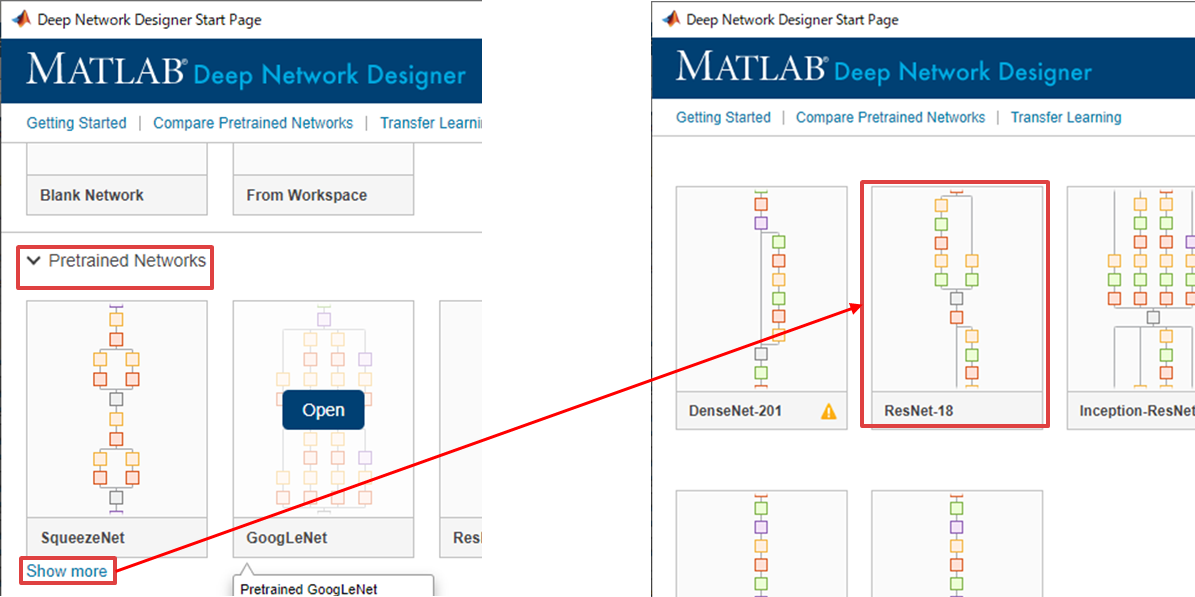

Select data layer by dragging and then remove them by pushing delete key

(Need to replace the input layer because the input size of the pretrained ResNet18 is 224 x 224 x 3 while the size of the training images is 180 x 320 x 3)

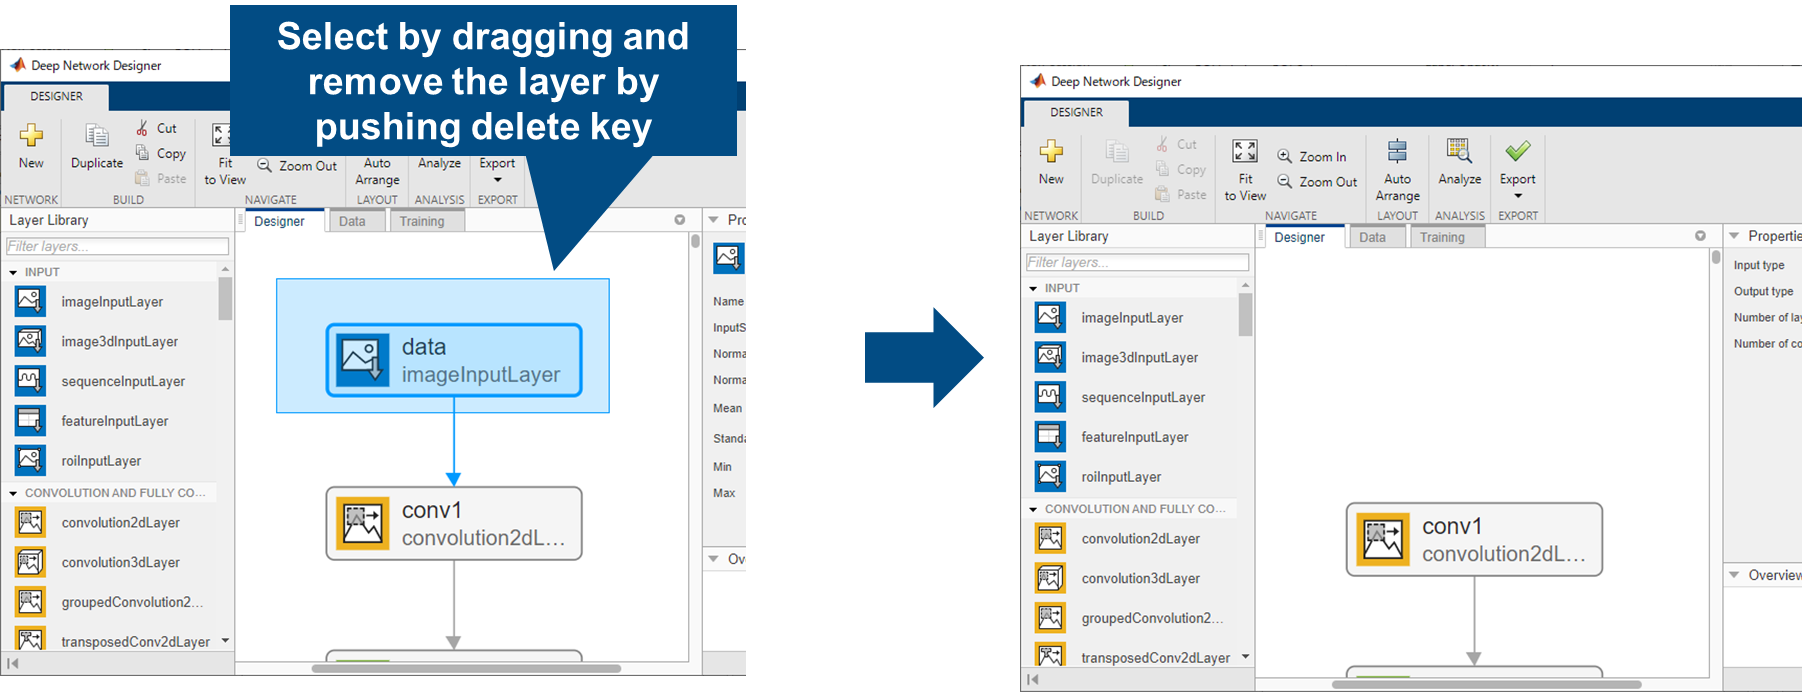

Drag & drop the "imageInputLayer" in the "INPUT" group in the "Layer Library" tab to the designer campus. Drag the edge of the `imageinput`layer to connect to the `conv1`. Set the "`InputSize`" property in the `imageinput` layer to "`180,320,3"`.

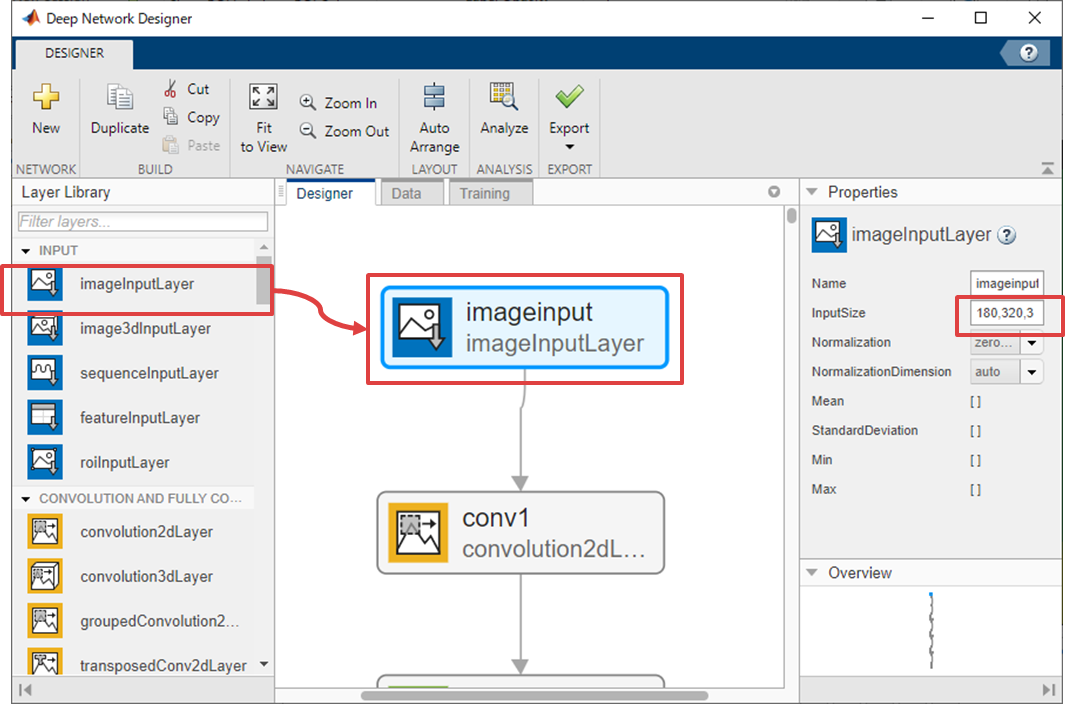

Select "`fc1000"`layer and the successive layers by dragging and then remove them by pushing delete key. (Need to change the 1,000 classes classification model to a 2 outputs regression model)

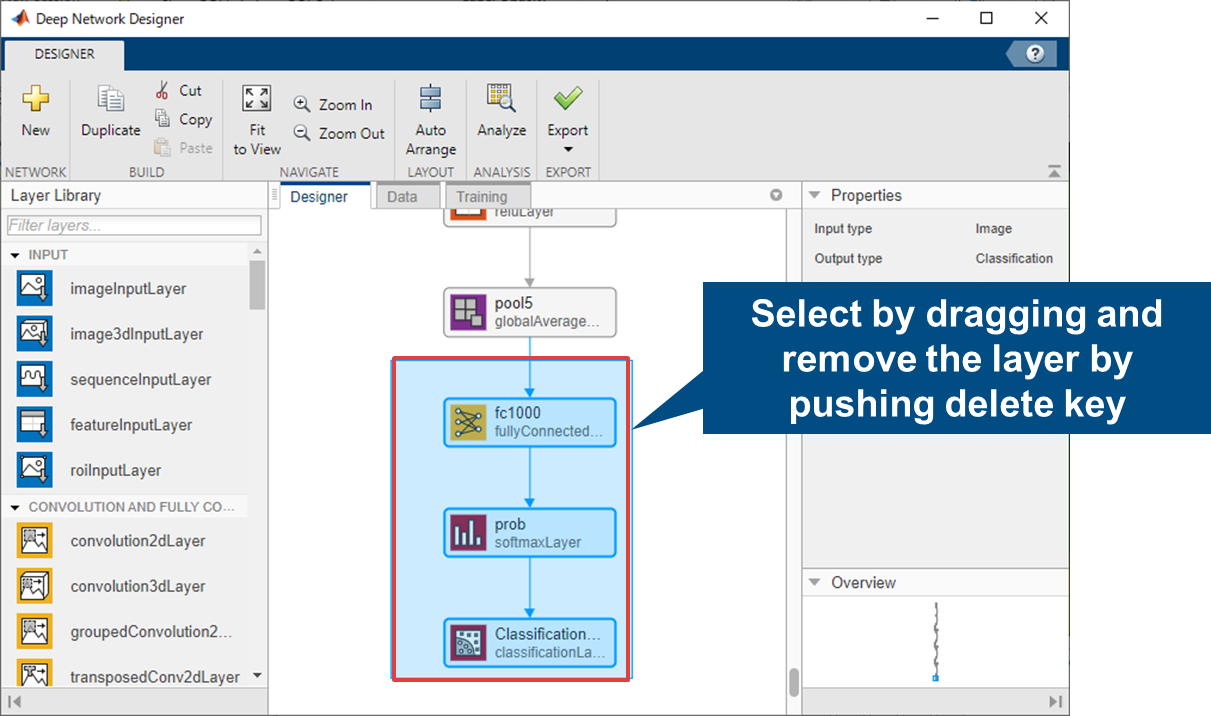

Add `fullyConnectedLayer` from "Convolution and fully connected layers" section and "`regressionLayer`" from "Output" section in "Layer Library" located in the left panel. Change the `OutputSize` to 2 because the number of output values are two (x, y). Connect `pool5` to `fc` and `fc` to `regressionOutput` respectively

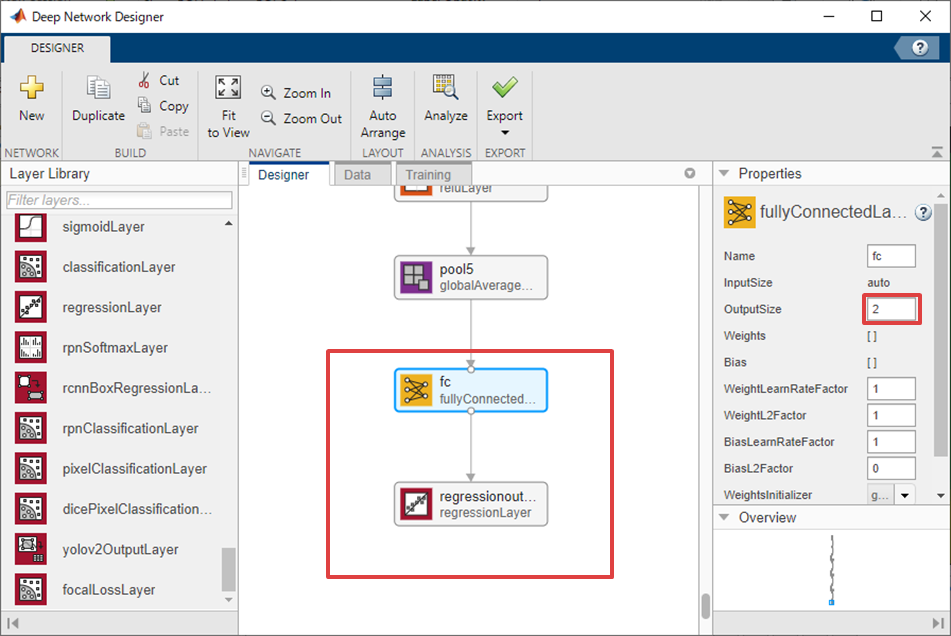

Make sure the network is consistent and the number of errors is zero by clicking "Analyze"button

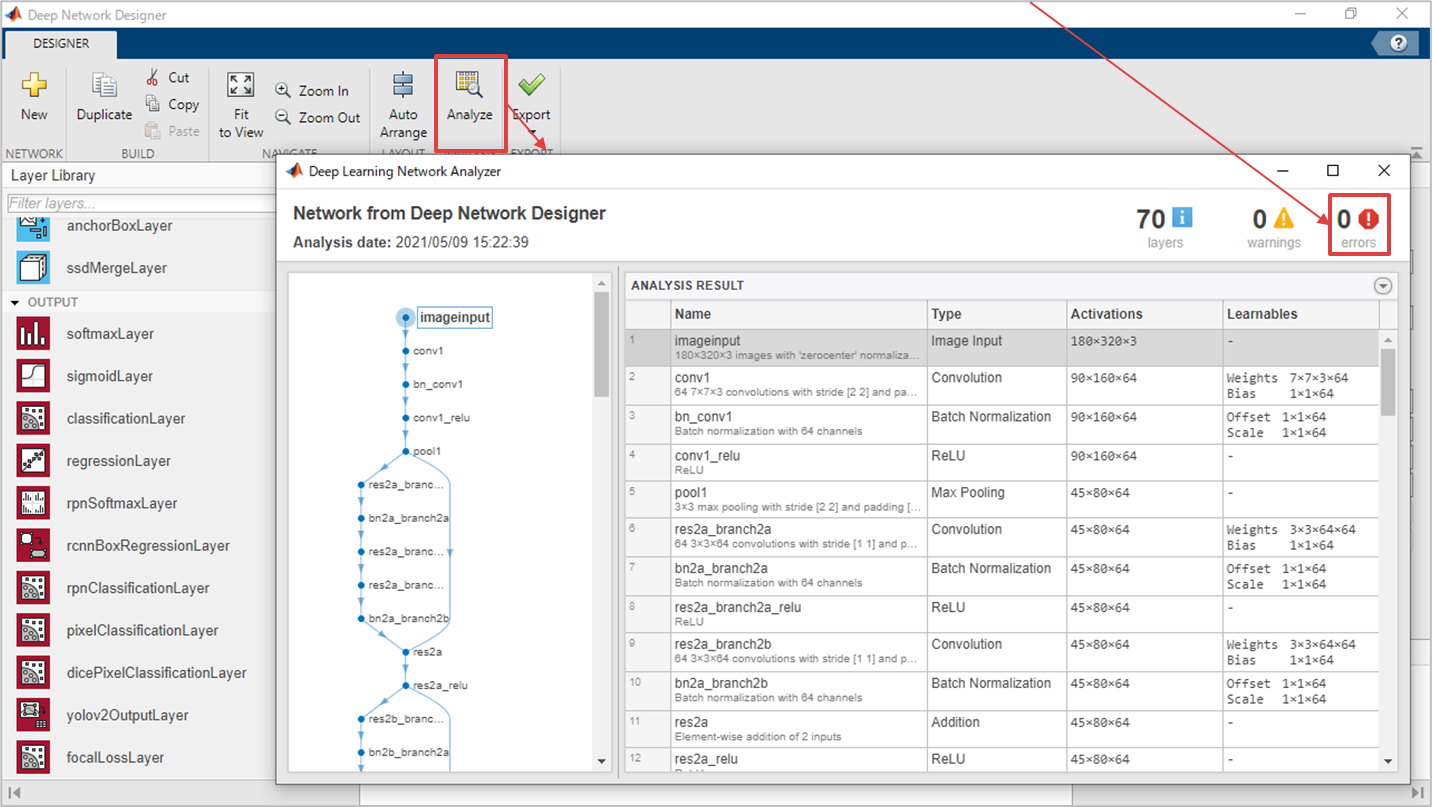

Export the model to workspace by clicking "Export" in "Export" button.

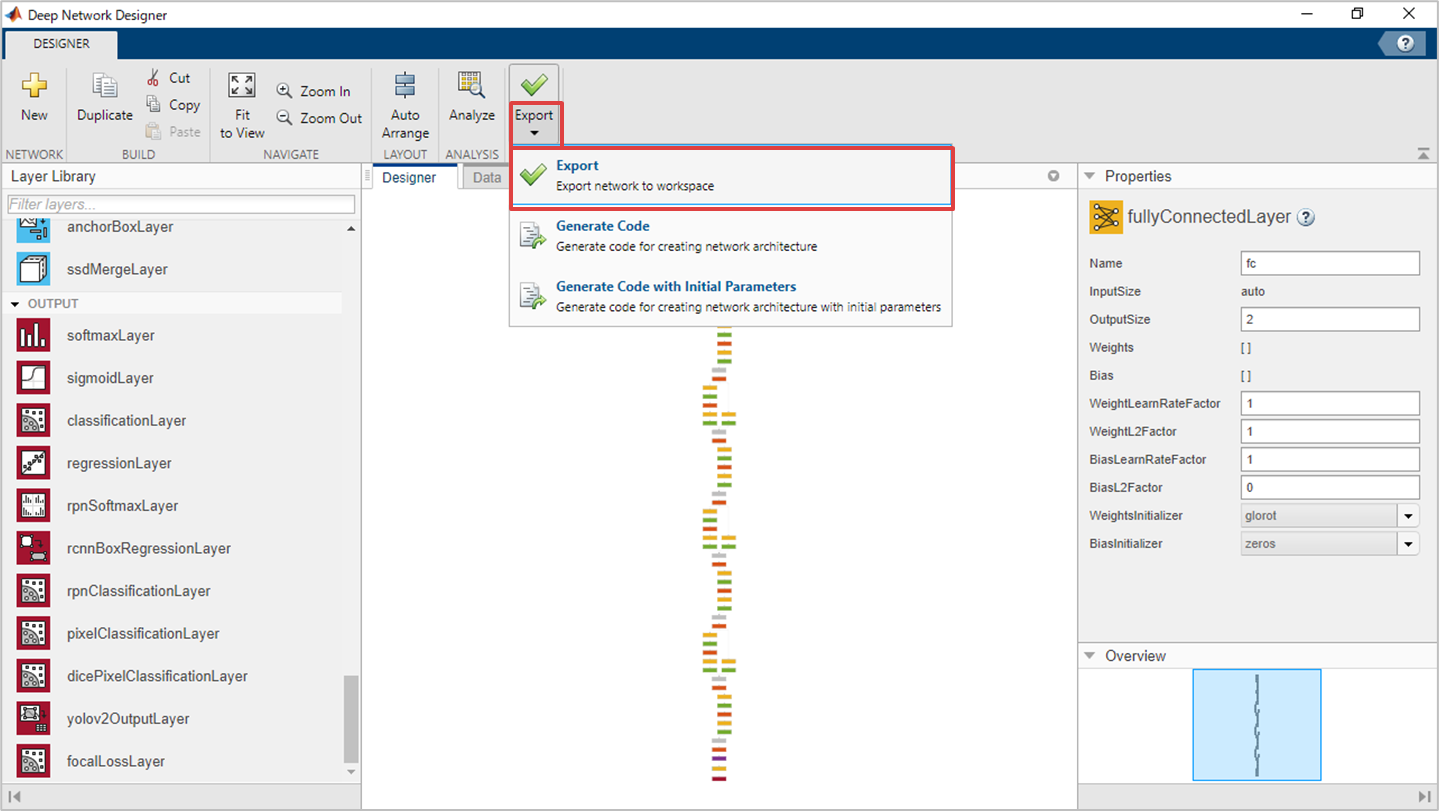

## **Setting the options for training **

`MaxEpochs`: Number of training set to be used. If the solution does not converge, incirease the number. 

`InitialLearnRate`: Initial leaning rate. Larger rate tend result in a divergence of the solution. Smaller rate increases the accuracy, however with more computational time. 

`LearnRateDropFactor`: A factor of the learning rate

`LearnRateDropPeriod`: number of epoch to reduce the learning rate 

options = trainingOptions('adam',...
    'MiniBatchSize',16,...
    'MaxEpochs',30,...
    'InitialLearnRate',1e-3,...
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropFactor',0.1, ...
    'LearnRateDropPeriod',20, ...
    'Shuffle','every-epoch',...
    'ResetInputNormalization',true,...
    'Verbose',true,...
    'Plots','training-progress');

## Training the network

if doTraining
    if exist('net_1','var')
        net = addLayers(net_1,regressionLayer("Name","regressionoutput"));
        net = connectLayers(net,net.Layers(end-1).Name,net.Layers(end).Name);
        lgraph_1 = layerGraph(net);
    end
    rng('default');
    trainedNet = trainNetwork(augTrainDs,lgraph_1,options);

    % Save the training results
    save('mynet_new','trainedNet');
else
    load('mynet.mat');
end

## **Validation of the trained network with dataset which is not used for training**

testDs.reset;
annotatedImages = {};
for i = 1:testDs.numpartitions
    data = read(testDs);
    imdata = data{1};
    posGt = data{2};
    pos = predict(trainedNet,imdata);
    pos = pos .* (wh(1)/2) + wh(1)/2;
    posGt = posGt .* (wh(1)/2) + wh(1)/2;
    annotatedImages{i} = insertShape(data{1,1}, 'FilledCircle', [posGt 5],'Color','Green');
    annotatedImages{i} = insertShape(annotatedImages{i},'Line', [wh(1)/2, wh(2), posGt],...
        'LineWidth',3,'Color','Green');
    annotatedImages{i} = insertShape(annotatedImages{i}, 'FilledCircle', [pos 5],'Color','Red');
    annotatedImages{i} = insertShape(annotatedImages{i},'Line', [wh(1)/2, wh(2), pos],...
        'LineWidth',3,'Color','Red');
end
figure;
montage(annotatedImages);

## Next step

Open [line_follower.slx](matlab:open('line_follower.slx')) and run it to perform a line following with the trained network.

## [Return to menu](matlab:open('workshopMenu.mlx'))

function data = augmentData(A)
% Apply random horizontal flipping, and random X/Y scaling. Boxes that get
% scaled outside the bounds are clipped if the overlap is above 0.25. Also,
% jitter image color.

data = cell(size(A));
for ii = 1:size(A,1)
    I = A{ii,1};
    pos = A{ii,2};
    sz = size(I);

    %if numel(sz) == 3 && sz(3) == 3
    %    I = jitterColorHSV(I,...
    %        'Contrast',[0.2 0.8],...
    %        'Hue',0.05,...
    %        'Saturation',0.1,...
    %        'Brightness',0.2);
    %end

    % Randomly flip image.
    tform = randomAffine2d('XReflection',true);
    rout = affineOutputView(sz,tform,'BoundsStyle','centerOutput');
    I = imwarp(I,tform,'OutputView',rout);

    % Apply same transform to boxes.
    pos = tform.transformPointsForward(pos);

    data(ii,:) = {I, pos};
end
end

*Copyright 2021 The MathWorks, Inc.*